%{ 
Group 3:
1. Steve Vinsensius Jo - V01099466
2. Likkhith Krishnamurthy Aditya - V01098937
%}

Task 1:

Reload the Class A, B and C data from Exercise 1 and generated the Bayes decision boundaries for equal a priori class probabilities.

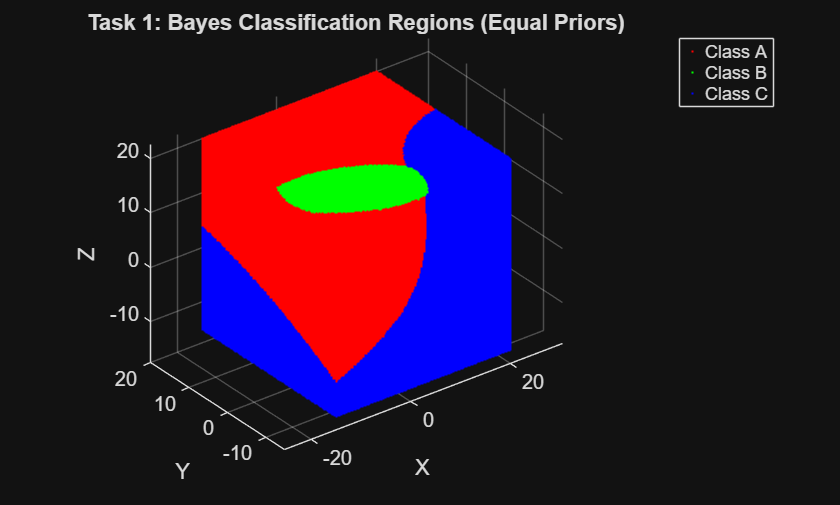

mu_A = [0; 4; 7];
sigma_A = [6.5000, 2.1651, 1.2500; 2.1651, 5.1250, 2.3816; 1.2500, 2.3816, 2.3750];
mu_B = [10; 5; 5];
sigma_B = [3.0184, 0.4331, -1.4481; 0.4331, 0.9436, -0.6456; -1.4481, -0.6456, 1.2880];
mu_C = [-2; -5; -5];
sigma_C = [6.8928, -1.3750, 3.1945; -1.3750, 3.3572, 0.6945; 3.1945, 0.6945, 3.7500];
% reload the Class A, B and C data saved at the end of Exercise 1
load('exercise1_data.mat', 'samples_A', 'samples_B', 'samples_C');
Vaxis = [-15 20 -15 20 -15 20];
Num = 120;
gridPoints = vol3D(Vaxis, Num);

% discriminant function
% different from exercise 1 (with addition of prior)
function g = discriminant(X, mu, sigma, prior)
% X     = N x D matrix of points
% mu    = D x 1 mean vector
% sigma = D x D covariance matrix
% prior = scalar P(class); defaults to 1 (no prior term = Exercise 1 behaviour)
 
% nargin: number of inputs
if nargin < 4
    prior = 1;
end
 
Xc = X - mu';
invSigma = inv(sigma);
logDetSigma = log(det(sigma));
 
quadForm = sum((Xc * invSigma) .* Xc, 2);
 
g = -0.5 * quadForm - 0.5 * logDetSigma + log(prior);
end

priorA = 1/3; priorB = 1/3; priorC = 1/3;
 
g_A = discriminant(gridPoints, mu_A, sigma_A, priorA);
g_B = discriminant(gridPoints, mu_B, sigma_B, priorB);
g_C = discriminant(gridPoints, mu_C, sigma_C, priorC);
 
allG = [g_A, g_B, g_C];
[~, classLabels] = max(allG, [], 2);
 
figure;
colors = {'r','g','b'};
hold on;
for c = 1:3
    mask = classLabels == c;
    plot3(gridPoints(mask,1), gridPoints(mask,2), gridPoints(mask,3), '.', 'Color', colors{c}, 'MarkerSize', 2);
end
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Task 1: Bayes Classification Regions (Equal Priors)');
grid on; axis equal; view(3);
legend('Class A','Class B','Class C');

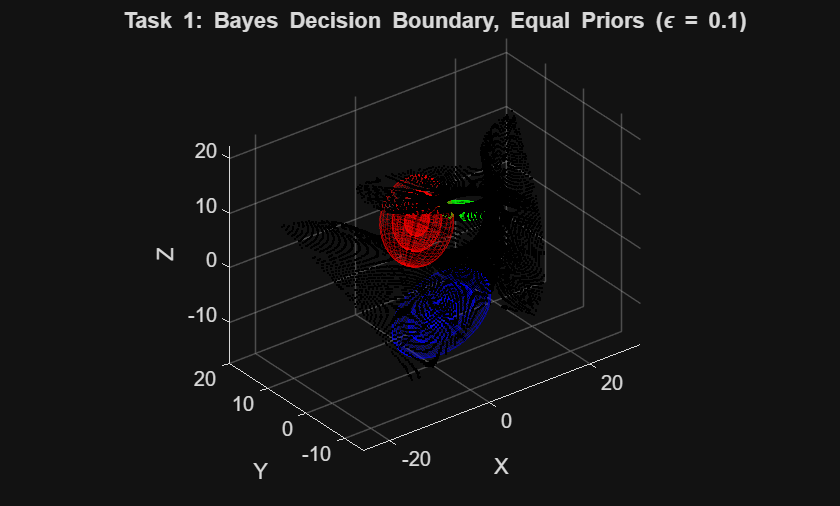

 

sortedG = sort(allG, 2, 'descend');
topGap = sortedG(:,1) - sortedG(:,2);
 
epsilon = 0.1;
boundaryMask = abs(topGap) < epsilon;
boundaryPoints = gridPoints(boundaryMask, :);

 

gridFine = vol3D(Vaxis, 200);
gFine = [discriminant(gridFine, mu_A, sigma_A, priorA), discriminant(gridFine, mu_B, sigma_B, priorB), discriminant(gridFine, mu_C, sigma_C, priorC)];
sFine = sort(gFine, 2, 'descend');
boundaryFine = gridFine(sFine(:,1) - sFine(:,2) < epsilon, :);
clear gridFine gFine sFine       

function plotGaussianEllipsoid(mu, sigma, color, nStdList)
% 1, 2, 3 standard-deviation contours and principal axes
[phi, lambda] = eig(sigma);
eigVals = diag(lambda);
hold on;
for n = nStdList
    [X, Y, Z] = ellipsoid(0,0,0,1,1,1,30);
    pts = [X(:), Y(:), Z(:)];
    shifted = pts * diag(n * sqrt(eigVals)) * phi' + mu';
    surf(reshape(shifted(:,1), size(X)), reshape(shifted(:,2), size(Y)), ...
         reshape(shifted(:,3), size(Z)), 'FaceColor', 'none', 'EdgeColor', color, 'EdgeAlpha', 0.3);
end
for i = 1:length(eigVals)
    axisVec = phi(:,i) * 3 * sqrt(eigVals(i));
    p1 = mu - axisVec;  p2 = mu + axisVec;
    line([p1(1) p2(1)], [p1(2) p2(2)], [p1(3) p2(3)], 'Color', 'k', 'LineWidth', 1.5);
end
end

figure; hold on;
plot3(boundaryFine(:,1), boundaryFine(:,2), boundaryFine(:,3), 'k.', 'MarkerSize', 2);
plotGaussianEllipsoid(mu_A, sigma_A, 'r', [1 2 3]);
plotGaussianEllipsoid(mu_B, sigma_B, 'g', [1 2 3]);
plotGaussianEllipsoid(mu_C, sigma_C, 'b', [1 2 3]);
xlabel('X'); ylabel('Y'); zlabel('Z');
title(sprintf('Task 1: Bayes Decision Boundary, Equal Priors (\\epsilon = %g)', epsilon));
grid on; axis equal; view(3);

Task 2

Assess the degree to which changes to the means and covariance of the data classes produces changes the nature of the generated inter-class Bayes decision boundaries.

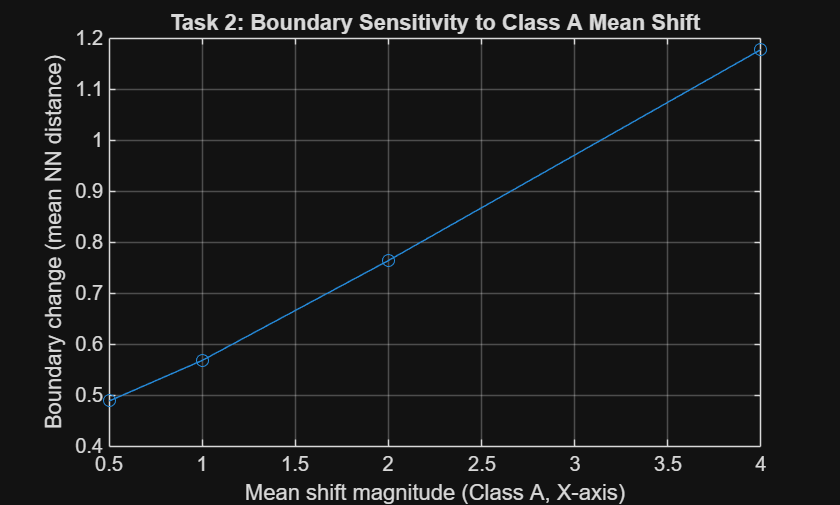

% reproducability of Bayes Boundary Points based on Bayes Decision Boundary
% from exercise 1
function [boundaryPoints, labels] = computeBayesBoundary(mu_A, sigma_A, mu_B, sigma_B, mu_C, sigma_C, ...
    priorA, priorB, priorC, gridPoints, epsilon)
g_A = discriminant(gridPoints, mu_A, sigma_A, priorA);
g_B = discriminant(gridPoints, mu_B, sigma_B, priorB);
g_C = discriminant(gridPoints, mu_C, sigma_C, priorC);
 
allG = [g_A, g_B, g_C];
[~, labels] = max(allG, [], 2);
sortedG = sort(allG, 2, 'descend');
topGap = sortedG(:,1) - sortedG(:,2);
 
boundaryMask = abs(topGap) < epsilon;
boundaryPoints = gridPoints(boundaryMask, :);
end

% 
function d = boundaryChangeMetric(baselineBoundary, perturbedBoundary)
if isempty(baselineBoundary) || isempty(perturbedBoundary)
    d = NaN;
    return;
end
d1 = mean(min(pdist2(baselineBoundary, perturbedBoundary), [], 2));
d2 = mean(min(pdist2(perturbedBoundary, baselineBoundary), [], 2));
d = (d1 + d2) / 2;
end

% using the original mean and covariance to act as the baseline boundary
baselineBoundary = computeBayesBoundary(mu_A, sigma_A, mu_B, sigma_B, mu_C, sigma_C, ...
    priorA, priorB, priorC, gridPoints, epsilon);

% test with different magnitude shift of the mean along one axis
meanShiftMagnitudes = [0.5, 1, 2, 4];
meanShiftChange = zeros(size(meanShiftMagnitudes));

% test on class A
for i = 1:length(meanShiftMagnitudes)
    delta = meanShiftMagnitudes(i);
    mu_A_shifted = mu_A + [delta; 0; 0];  % shift along X only
    perturbedBoundary = computeBayesBoundary(mu_A_shifted, sigma_A, mu_B, sigma_B, mu_C, sigma_C, ...
        priorA, priorB, priorC, gridPoints, epsilon);
    meanShiftChange(i) = boundaryChangeMetric(baselineBoundary, perturbedBoundary);
end

% Mean Shift figure for class A
figure;
plot(meanShiftMagnitudes, meanShiftChange, '-o');
xlabel('Mean shift magnitude (Class A, X-axis)');
ylabel('Boundary change (mean NN distance)');
title('Task 2: Boundary Sensitivity to Class A Mean Shift');
grid on;

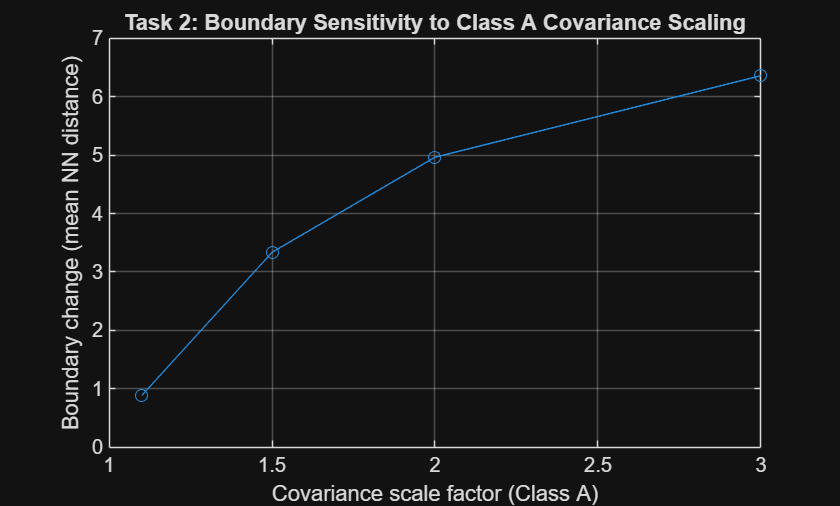

 
% test with different magnitude shift of the covariance along one axis
covScaleFactors = [1.1, 1.5, 2, 3];
covScaleChange = zeros(size(covScaleFactors));
 
for i = 1:length(covScaleFactors)
    scale = covScaleFactors(i);
    sigma_A_scaled = sigma_A * scale;
 
    perturbedBoundary = computeBayesBoundary(mu_A, sigma_A_scaled, mu_B, sigma_B, mu_C, sigma_C, ...
        priorA, priorB, priorC, gridPoints, epsilon);
 
    covScaleChange(i) = boundaryChangeMetric(baselineBoundary, perturbedBoundary);
end

% Covariance Shift figure for class A
figure;
plot(covScaleFactors, covScaleChange, '-o');
xlabel('Covariance scale factor (Class A)');
ylabel('Boundary change (mean NN distance)');
title('Task 2: Boundary Sensitivity to Class A Covariance Scaling');
grid on;

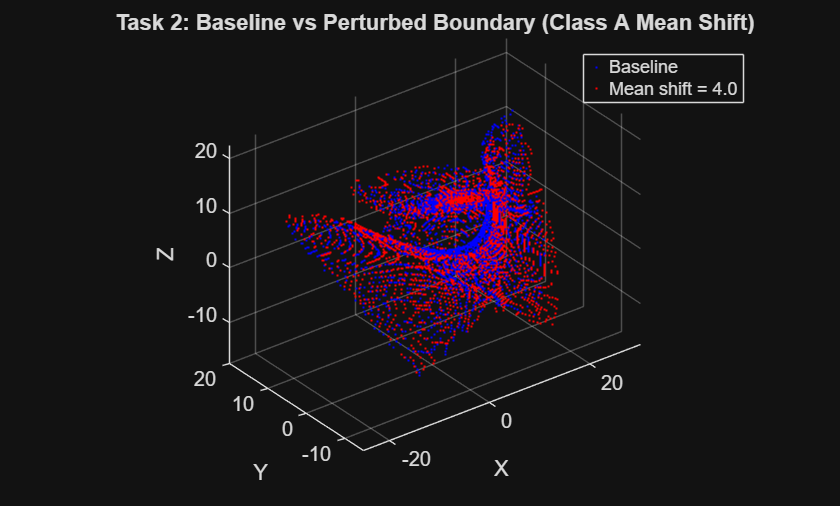


% visualize baseline vs one of the representative perturbed case (largest
% mean shift)
mu_A_example = mu_A + [meanShiftMagnitudes(end); 0; 0];
perturbedBoundaryExample = computeBayesBoundary(mu_A_example, sigma_A, mu_B, sigma_B, mu_C, sigma_C, priorA, priorB, priorC, gridPoints, epsilon);

% blue = using baseline boundary
% red = using the perturbed boundary
figure;
hold on;
plot3(baselineBoundary(:,1), baselineBoundary(:,2), baselineBoundary(:,3), '.', ...
    'Color', 'b', 'MarkerSize', 3, 'DisplayName', 'Baseline');
plot3(perturbedBoundaryExample(:,1), perturbedBoundaryExample(:,2), perturbedBoundaryExample(:,3), '.', ...
    'Color', 'r', 'MarkerSize', 3, 'DisplayName', sprintf('Mean shift = %.1f', meanShiftMagnitudes(end)));
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Task 2: Baseline vs Perturbed Boundary (Class A Mean Shift)');
legend show;
grid on; axis equal; view(3);

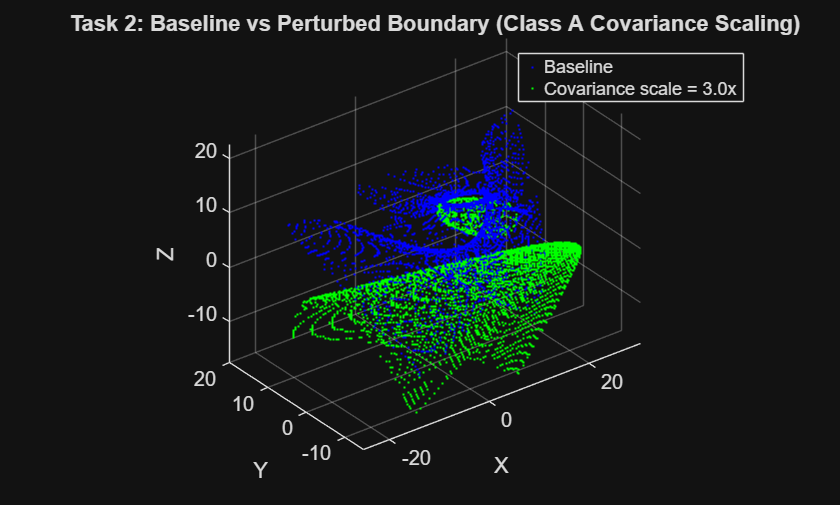


% visualize baseline vs one of the representative perturbed case (largest
% covariance shift)
sigma_A_example = sigma_A * covScaleFactors(end);
perturbedBoundaryCovExample = computeBayesBoundary(mu_A, sigma_A_example, mu_B, sigma_B, mu_C, sigma_C, ...
    priorA, priorB, priorC, gridPoints, epsilon);

% blue = using baseline boundary
% green = using the perturbed boundary
figure;
hold on;
plot3(baselineBoundary(:,1), baselineBoundary(:,2), baselineBoundary(:,3), '.', ...
    'Color', 'b', 'MarkerSize', 3, 'DisplayName', 'Baseline');
plot3(perturbedBoundaryCovExample(:,1), perturbedBoundaryCovExample(:,2), perturbedBoundaryCovExample(:,3), '.', ...
    'Color', 'g', 'MarkerSize', 3, 'DisplayName', sprintf('Covariance scale = %.1fx', covScaleFactors(end)));
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Task 2: Baseline vs Perturbed Boundary (Class A Covariance Scaling)');
legend show;
grid on; axis equal; view(3);

`While moving class mean will influence the boundaries themselves, varying the covariance will change their nature. Shifting the mean of class A in x-direction gave proportionate changes in boundaries from 0.49 for the shift by 0.5 units to 1.18 for a shift by 4 units, implying that changing mean by a small amount will lead to a small change in boundaries. Conversely, changing the covariance matrix greatly affected the boundaries, increasing the latter rapidly depending on the scale factor (from 0.89 at 1.1x scale to 6.36 at 3x scale).`

`The explanation for the difference lies in the different influence of the two parameters on the discriminant function. While the covariance matrix contributes to the discriminant function through the formulas -1/2 x' inv(sigma) x and -1/2 log(det(sigma)), the former being responsible for the boundaries due to its defining of the shape of boundaries, the mean affects the discriminant function only through linear and constant terms.`

Task 3

Provide two example cases where relatively minor variations in the class A, B, and C means and/or covariances lead to quite significant changes in the 3-D plotted multi-class decision boundary. Provide two separate plots showing differences in the produced 3-D boundaries.

Describe why small changes in the class means and/or covariances can lead to large changes in the decision boundary’s shape and form,

% Case 1: widen class A's covariance by 20% (each standard deviation is about 9.5% larger)
sigma_A_case1 = sigma_A * 1.2;
[bCase1, labCase1] = computeBayesBoundary(mu_A, sigma_A_case1, mu_B, sigma_B, mu_C, sigma_C, priorA, priorB, priorC, gridPoints, epsilon);
 
% Case 2: move class A's mean by 0.5 units along A's minor principal axis.
% uMinor is the eigenvector of sigma_A with the smallest eigenvalue (1),
% so 0.5 units is 0.5 standard deviations (check with eig(sigma_A)).
uMinor = [0; -0.5; sqrt(3)/2];
mu_A_case2 = mu_A + 0.5 * uMinor;
[bCase2, labCase2] = computeBayesBoundary(mu_A_case2, sigma_A, mu_B, sigma_B, mu_C, sigma_C, priorA, priorB, priorC, gridPoints, epsilon);
 
fprintf("Case 1 (sigma_A x 1.2): boundary change = %.3f, volume relabelled = %.2f%%\n", boundaryChangeMetric(baselineBoundary, bCase1), 100*mean(labCase1 ~= classLabels));

Case 1 (sigma_A x 1.2): boundary change = 1.469, volume relabelled = 9.37%


fprintf("Case 2 (mu_A + 0.5 along minor axis): boundary change = %.3f, volume relabelled = %.2f%%\n", boundaryChangeMetric(baselineBoundary, bCase2), 100*mean(labCase2 ~= classLabels));

Case 2 (mu_A + 0.5 along minor axis): boundary change = 0.752, volume relabelled = 3.11%


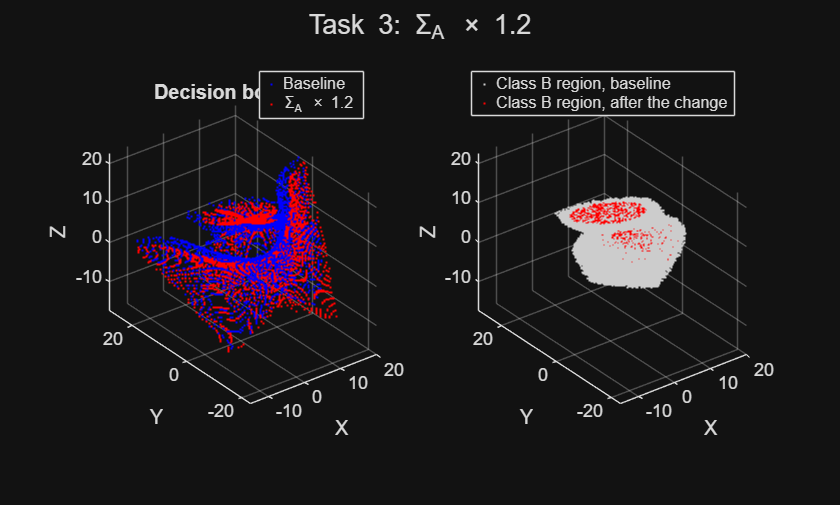

 
% left: baseline vs changed boundary; right: class B's region before and after
function plotTask3Case(gridPoints, baselineBoundary, bCase, labBase, labCase, caseName)
figure;
subplot(1,2,1); hold on;
plot3(baselineBoundary(:,1), baselineBoundary(:,2), baselineBoundary(:,3), '.', 'Color', 'b', 'MarkerSize', 3, 'DisplayName', 'Baseline');
plot3(bCase(:,1), bCase(:,2), bCase(:,3), '.', 'Color', 'r', 'MarkerSize', 3, 'DisplayName', caseName);
xlabel('X'); ylabel('Y'); zlabel('Z'); title('Decision boundary');
legend show; grid on; axis equal; view(3);
subplot(1,2,2); hold on;
inB0 = find(labBase == 2);  inB0 = inB0(1:4:end);
inB1 = find(labCase == 2);  inB1 = inB1(1:4:end);
plot3(gridPoints(inB0,1), gridPoints(inB0,2), gridPoints(inB0,3), '.', 'Color', [0.8 0.8 0.8], 'MarkerSize', 2, 'DisplayName', 'Class B region, baseline');
plot3(gridPoints(inB1,1), gridPoints(inB1,2), gridPoints(inB1,3), '.', 'Color', 'r', 'MarkerSize', 2, 'DisplayName', 'Class B region, after the change');
xlabel('X'); ylabel('Y'); zlabel('Z'); title('Class B region');
legend show; grid on; axis equal; view(3);
sgtitle(['Task 3: ' caseName]);
end
 
plotTask3Case(gridPoints, baselineBoundary, bCase1, classLabels, labCase1, '\Sigma_A \times 1.2');

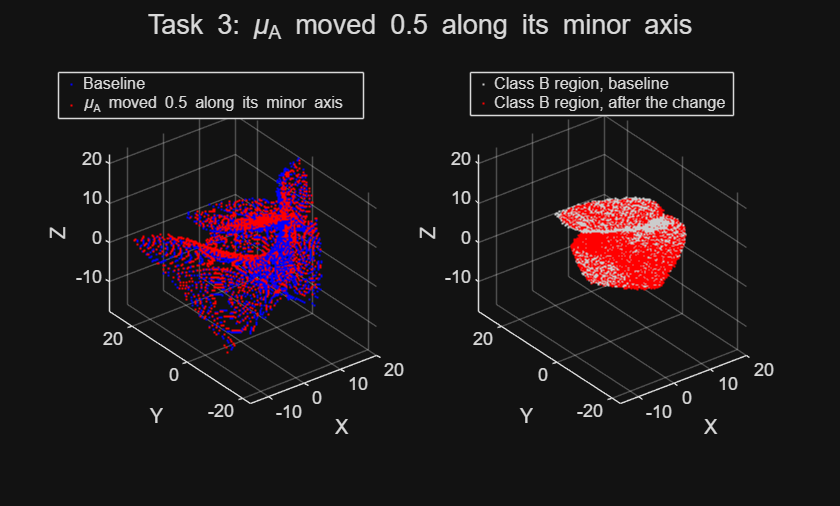

plotTask3Case(gridPoints, baselineBoundary, bCase2, classLabels, labCase2, '\mu_A moved 0.5 along its minor axis');

Two cases are presented where small changes have large effects on the boundary.

Case 1: The covariance of class A is increased by 20%, meaning that each of A's standard deviations is increased by only about 9.5%. About 9.4% of the volume changes classes, and the plot on the right shows that class B's region divides into two separate regions: the narrow neck in the middle of the B region closes up, and the upper region is left as an isolated region in the top corner of the volume, far away from any class B data points.

Case 2: Class A's mean is shifted by only 0.5 units (half a standard deviation) along the minor axis of A. About 3.1% of the volume changes classes, and again the region for class B divides into two regions even though B's mean and covariance remain unchanged.

Small changes can have large effects because:

1. The boundary is where two discriminants are equal. A shift in parameters displaces the boundary by roughly (g_i - g_j)' / |(g_i - g_j)'|, so where g_i - g_j varies slowly, a small displacement will move the boundary by a lot.

2. Most of the boundary on the plot occurs away from any data, where the decision is between tails of the densities for the classes. The rate of decay of the tails depends on inv(sigma), so small changes to covariances will flip the winning class over wide areas.

3. Region of class B gets squeezed into a thin neck. As a parameter changes, the neck becomes narrower and then suddenly class B's region breaks up, so near this point the boundary is very sensitive.

4. In the three-class case, a region belongs to a class only when that class beats both other classes, so a change in one class also affects the region of another class.

These changes occur mostly at points where there is no data at all, so the plot of the boundary changes a lot while the classification of data does not change much.

Task 4

Assess how these decision boundaries change with changes to the three class’s a priori probabilities.

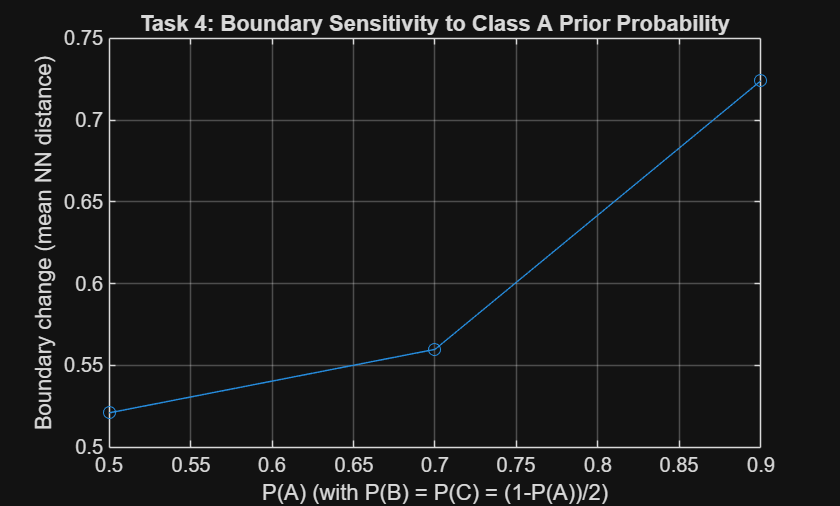

% baselineBoundary = the boundary at equal prior

% distribute the prior so they are not all equal.
priorSetsA = [0.5, 0.7, 0.9]; 
priorChange = zeros(size(priorSetsA));

for i = 1:length(priorSetsA)
    pA = priorSetsA(i);
    pB = (1 - pA) / 2;
    pC = (1 - pA) / 2;
 
    perturbedBoundary = computeBayesBoundary(mu_A, sigma_A, mu_B, sigma_B, mu_C, sigma_C, ...
        pA, pB, pC, gridPoints, epsilon);
 
    priorChange(i) = boundaryChangeMetric(baselineBoundary, perturbedBoundary);
end

figure;
plot(priorSetsA, priorChange, '-o');
xlabel('P(A) (with P(B) = P(C) = (1-P(A))/2)');
ylabel('Boundary change (mean NN distance)');
title('Task 4: Boundary Sensitivity to Class A Prior Probability');
grid on;

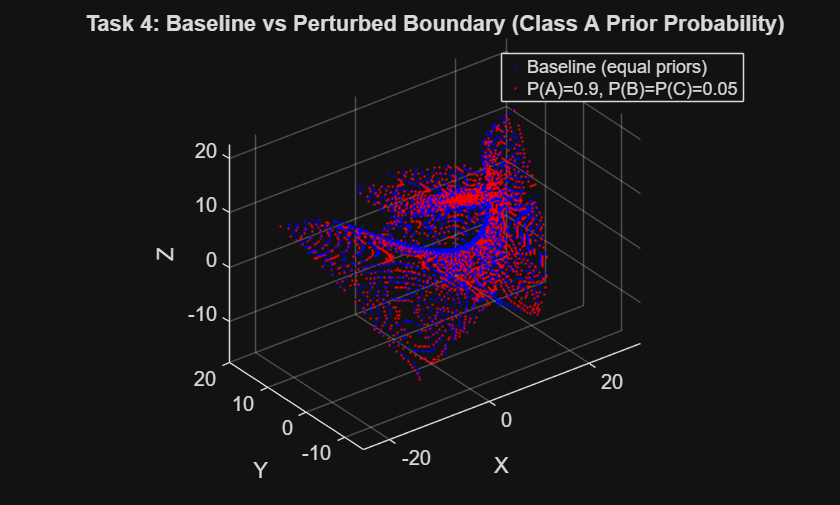

 
%% Visualize baseline vs one representative perturbed case (priorA = 0.9)
pA_example = priorSetsA(end);
pB_example = (1 - pA_example) / 2;
pC_example = (1 - pA_example) / 2;
 
perturbedPriorBoundaryExample = computeBayesBoundary(mu_A, sigma_A, mu_B, sigma_B, mu_C, sigma_C, pA_example, pB_example, pC_example, gridPoints, epsilon);

% blue = equal prior
% red = distributed (not equal) prior
figure;
hold on;
plot3(baselineBoundary(:,1), baselineBoundary(:,2), baselineBoundary(:,3), '.', 'Color', 'b', 'MarkerSize', 3, 'DisplayName', 'Baseline (equal priors)');
plot3(perturbedPriorBoundaryExample(:,1), perturbedPriorBoundaryExample(:,2), perturbedPriorBoundaryExample(:,3), '.', 'Color', 'r', 'MarkerSize', 3, 'DisplayName', sprintf('P(A)=%.1f, P(B)=P(C)=%.2f', pA_example, pB_example));
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Task 4: Baseline vs Perturbed Boundary (Class A Prior Probability)');
legend show;
grid on; axis equal; view(3);

Any change in prior probabilities affects the decision boundaries, although this effect is minor when compared to the changes in mean or covariances. Raising the value of P(A) from 1/3 to 0.9 (while P(B) = P(C) split the rest of the probability equally) led to the movement of the decision boundaries by a mean nearest-neighbour distance of 0.72; the decision boundaries also retained their shape.

The reason is that the prior probability becomes part of the discriminant function as a constant term, log P(i), which is independent of x. This alters the cut-off point at which one class defeats another and enlarges the region of the class with the larger prior, at the cost of the other classes, without affecting the coefficients responsible for the shape of the boundary. Only the boundaries that are adjacent to the class with a change in prior will be affected; these are the A/B and A/C surfaces, whereas the B/C surface does not move, since P(B) = P(C).

Task 5

Assess how these decision boundaries change with changes to the classes $\lambda_{\textrm{AA}}$, $\lambda_{\textrm{AB}}$, $\lambda_{\textrm{AC}}$, $\lambda_{\mathrm{BB}}$, $\lambda_{\textrm{BC}}$, and, $\lambda_{\textrm{CC}}$ loss functions, assuming $\lambda_{\textrm{AB}}$ = $\lambda_{\textrm{BA}}$, $\lambda_{\textrm{AC}}$ = $\lambda_{\textrm{CA}}$ and $\lambda_{\textrm{BC}}$ = $\lambda_{\textrm{CB}}$.

% function for Bayes Boundary Loss
function [boundaryPoints, labels] = computeBayesBoundaryLoss(mu_A, sigma_A, mu_B, sigma_B, mu_C, ...
    sigma_C,priorA, priorB, priorC, L, gridPoints, epsilon)
 
g = [discriminant(gridPoints, mu_A, sigma_A, priorA), discriminant(gridPoints, mu_B, sigma_B, priorB), discriminant(gridPoints, mu_C, sigma_C, priorC)];
 
% Log scores posteriors
g = g - max(g, [], 2);
post = exp(g);
post = post ./ sum(post, 2);
 
% Conditional risk for each candidate decision (N x 3)
risks = post * L';
[~, labels] = min(risks, [], 2);
 

sortedR = sort(risks, 2, 'ascend');
ratio = sortedR(:,2) ./ max(sortedR(:,1), realmin);
 
boundaryPoints = gridPoints(ratio < exp(epsilon), :);
end

%% 0-1 loss with equal priors
epsilonLoss = 0.1;
L01 = ones(3) - eye(3);
 
[lossBaselineBoundary, labL0] = computeBayesBoundaryLoss(mu_A, sigma_A, mu_B, sigma_B, mu_C, sigma_C, 1/3, 1/3, 1/3, L01, gridPoints, epsilonLoss);
 
fprintf("Boundary points (0-1 loss): %d\n", size(lossBaselineBoundary, 1));

Boundary points (0-1 loss): 3214


fprintf("Difference vs Task 1 baseline (mean NN distance): %.3f\n", boundaryChangeMetric(baselineBoundary, lossBaselineBoundary));

Difference vs Task 1 baseline (mean NN distance): 0.003


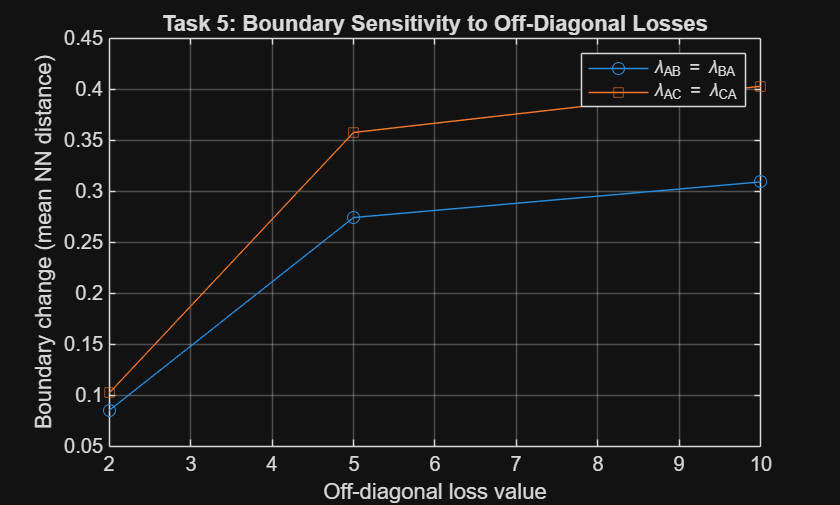

 
offDiagValues = [2, 5, 10];
changeAB = zeros(size(offDiagValues));
relAB = changeAB;  newC = changeAB;
 
for i = 1:length(offDiagValues)
    L = L01;
    L(1,2) = offDiagValues(i);
    L(2,1) = offDiagValues(i);
 
    [b, lab] = computeBayesBoundaryLoss(mu_A, sigma_A, mu_B, sigma_B, mu_C, sigma_C, 1/3, 1/3, 1/3, L, gridPoints, epsilonLoss);
    changeAB(i) = boundaryChangeMetric(lossBaselineBoundary, b);
    relAB(i) = 100*mean(lab ~= labL0);
    newC(i)  = 100*mean(lab == 3 & labL0 ~= 3);
end
 
changeAC = zeros(size(offDiagValues));
relAC = changeAC;  newB = changeAC;
 
for i = 1:length(offDiagValues)
    L = L01;
    L(1,3) = offDiagValues(i);
    L(3,1) = offDiagValues(i);
 
    [b, lab] = computeBayesBoundaryLoss(mu_A, sigma_A, mu_B, sigma_B, mu_C, sigma_C, 1/3, 1/3, 1/3, L, gridPoints, epsilonLoss);
    changeAC(i) = boundaryChangeMetric(lossBaselineBoundary, b);
    relAC(i) = 100*mean(lab ~= labL0);
    newB(i)  = 100*mean(lab == 2 & labL0 ~= 2);
end
 
figure;
plot(offDiagValues, changeAB, '-o', 'DisplayName', '\lambda_{AB} = \lambda_{BA}');
hold on;
plot(offDiagValues, changeAC, '-s', 'DisplayName', '\lambda_{AC} = \lambda_{CA}');
xlabel('Off-diagonal loss value');
ylabel('Boundary change (mean NN distance)');
title('Task 5: Boundary Sensitivity to Off-Diagonal Losses');
legend show; grid on;

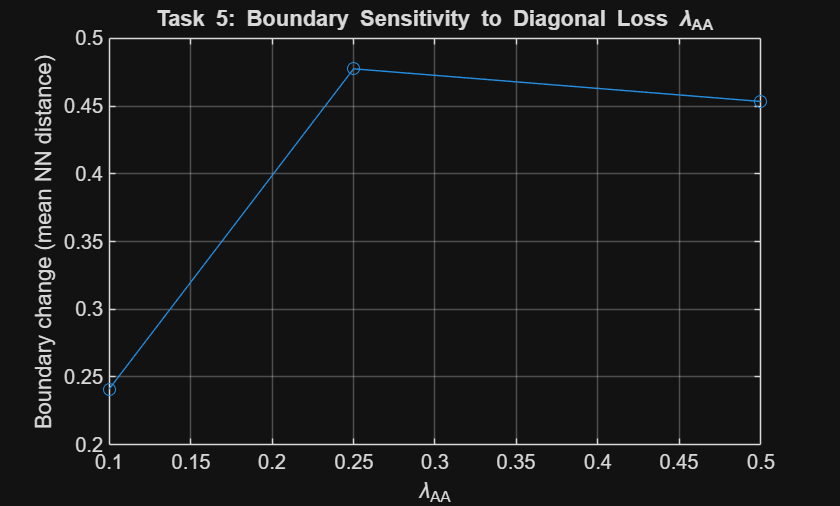

 
diagValues = [0.1, 0.25, 0.5];
changeDiag = zeros(size(diagValues));
relAA = changeDiag;
 
for i = 1:length(diagValues)
    L = L01;
    L(1,1) = diagValues(i);
 
    [b, lab] = computeBayesBoundaryLoss(mu_A, sigma_A, mu_B, sigma_B, mu_C, sigma_C, 1/3, 1/3, 1/3, L, gridPoints, epsilonLoss);
    changeDiag(i) = boundaryChangeMetric(lossBaselineBoundary, b);
    relAA(i) = 100*mean(lab ~= labL0);
end

figure;
plot(diagValues, changeDiag, '-o');
xlabel('\lambda_{AA}');
ylabel('Boundary change (mean NN distance)');
title('Task 5: Boundary Sensitivity to Diagonal Loss \lambda_{AA}');
grid on;

 
fprintf("lambda_AB sweep: %s\n", mat2str(changeAB, 3));

lambda_AB sweep: [0.0851 0.274 0.309]


fprintf("lambda_AC sweep: %s\n", mat2str(changeAC, 3));

lambda_AC sweep: [0.102 0.358 0.403]


fprintf("lambda_AA sweep: %s\n", mat2str(changeDiag, 3));

lambda_AA sweep: [0.241 0.478 0.453]



fprintf("lambda_AB sweep, %% of volume relabelled: %s, switched to C: %s\n", mat2str(relAB, 3), mat2str(newC, 3));

lambda_AB sweep, % of volume relabelled: [0.0193 0.914 1.43], switched to C: [0.0193 0.914 1.43]


fprintf("lambda_AC sweep, %% of volume relabelled: %s, switched to B: %s\n", mat2str(relAC, 3), mat2str(newB, 3));

lambda_AC sweep, % of volume relabelled: [0.0192 1.54 2.43], switched to B: [0.0192 1.54 2.43]


fprintf("lambda_AA sweep, %% of volume relabelled: %s\n", mat2str(relAA, 3));

lambda_AA sweep, % of volume relabelled: [0.0935 0.252 0.597]


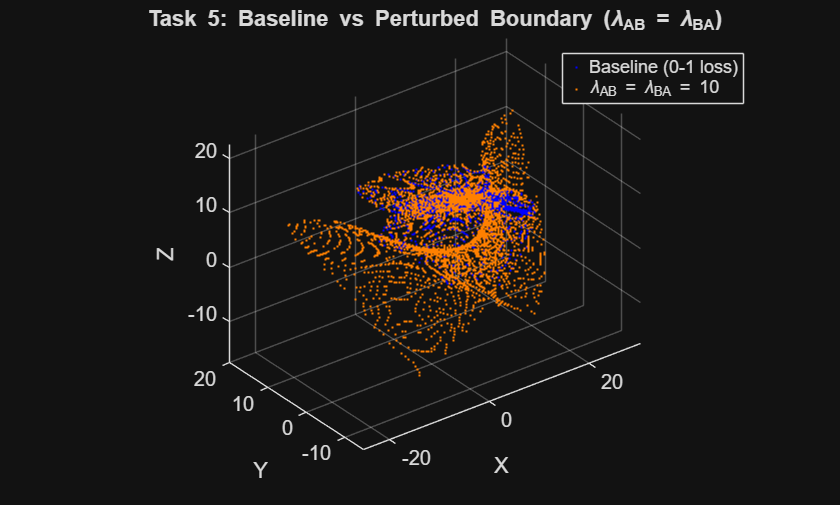

 
% largest lambda_AB = lambda_BA
L = L01; L(1,2) = offDiagValues(end); L(2,1) = offDiagValues(end);
bAB = computeBayesBoundaryLoss(mu_A, sigma_A, mu_B, sigma_B, mu_C, sigma_C, 1/3, 1/3, 1/3, L, gridPoints, epsilonLoss);

% blue = baseline boundary loss
% orange = perturbed boundary loss
figure;
hold on;
plot3(lossBaselineBoundary(:,1), lossBaselineBoundary(:,2), lossBaselineBoundary(:,3), '.', 'Color', 'b', 'MarkerSize', 3, 'DisplayName', 'Baseline (0-1 loss)');
plot3(bAB(:,1), bAB(:,2), bAB(:,3), '.', 'Color', [1 0.5 0], 'MarkerSize', 3, 'DisplayName', sprintf('\\lambda_{AB} = \\lambda_{BA} = %g', offDiagValues(end)));
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Task 5: Baseline vs Perturbed Boundary (\lambda_{AB} = \lambda_{BA})');
legend show; grid on; axis equal; view(3);

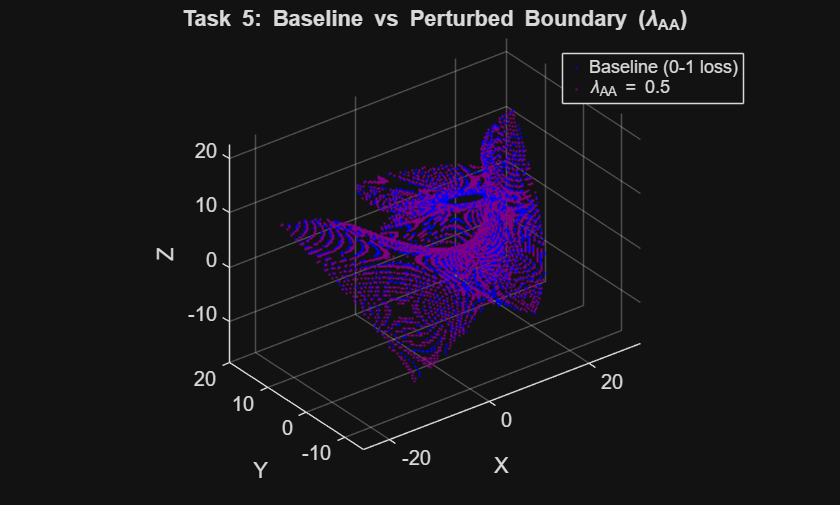

 
% largest lambda_AA = 0.5
L = L01; L(1,1) = diagValues(end);
bAA = computeBayesBoundaryLoss(mu_A, sigma_A, mu_B, sigma_B, mu_C, sigma_C, 1/3, 1/3, 1/3, L, gridPoints, epsilonLoss);
 
figure;
hold on;
plot3(lossBaselineBoundary(:,1), lossBaselineBoundary(:,2), lossBaselineBoundary(:,3), '.', 'Color', 'b', 'MarkerSize', 3, 'DisplayName', 'Baseline (0-1 loss)');
plot3(bAA(:,1), bAA(:,2), bAA(:,3), '.', 'Color', [0.5 0 0.5], 'MarkerSize', 3, 'DisplayName', sprintf('\\lambda_{AA} = %g', diagValues(end)));
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Task 5: Baseline vs Perturbed Boundary (\lambda_{AA})');
legend show; grid on; axis equal; view(3);

In 0-1 loss, the minimum risk rule is identical to the Bayes rule with equal prior, so its boundary is identical to Task 1. The tiny **0.003** difference arises solely from the different procedure used to identify boundary points.

Increasing lambda_AB = lambda_BA makes little difference below 2 but a significant difference above that level: 0.02%, 0.91% and 1.43% of the volume change class as lambda_AB equals 2, 5 and 10 respectively, all switching to class C. When A and B have the same probability, choosing either entails a risk of roughly lambda_AB/2, whereas choosing C entails a risk of roughly 1, thus for lambda_AB greater than 2, the classifier will choose class C: an inevitable mistake, but a relatively cheap one. A strip of class C emerges between classes A and B, far removed from the actual data of class C. Increasing lambda_AC = lambda_CA produces the same effect with class B, which dominates the area between A and C (0.02%, 1.54% and 2.43%).

Increasing lambda_AA will reduce class A's volume at a steady pace: 0.09%, 0.25% and 0.60% of the total volume will get reassigned when lambda_AA is 0.1, 0.25 and 0.5, respectively. In this case, where all other lambdas are equal to 1, the risk of decision A becomes 1-(1-lambda_AA)*P(A|x). Hence, lambda_AA acts precisely the same way as multiplying the prior probability of A by (1-lambda_AA). For lambda_AA >= 1, it is always more expensive to decide A and class A disappears completely.*

*In the absence of any diagonal losses and assuming lambda_ij=lambda_ji, the border between two classes cannot possibly change. Indeed, lambda*

P(A|x) > lambda*P(B|x) is equivalent to P(A|x) > P(B|x). The losses become relevant only because there is a third class that could be a more **cheaper**  choice.

The average nearest neighbor distance cannot adequately capture these effects because it cannot detect the appearance of a strip of class C between classes A and B, and, as lambda_AA increases, it decreases from 0.478 to 0.453 while the relabeled volume is still increasing. That is why the percentage of the total volume that gets reassigned is also provided.

make the latex changes , do not change any text

Task 6

Now introduce outlier data points to one of the classes at a 10, 50, and 100 standard deviations from that class’s mean and regenerate the Bayes class boundaries. Note measuring how far a point is from the mean of a class in terms of that class’s standard deviations is defined be a measurement of that point’s Mahalanobis distance from the mean.    

    • Discuss the impacts that such single outlier data points can have   

    on the resulting nature of the inter-class Bayes decision boundaries.

% place a point at the mahalanobis distance (d)
function xOut = makeOutlier(mu, sigma, d, u)
% mu    = 3x1 class mean
% sigma = 3x3 class covariance
% d     = Mahalanobis distance (number of "standard deviations")
% u     = 3x1 unit direction in whitened space
% Returns a 1x3 point x with sqrt((x-mu)' * inv(sigma) * (x-mu)) = d.
[V, D] = eig(sigma);
xOut = mu(:)' + d * (V * sqrt(D) * u(:))';
end

mu_A_hat = mean(samples_A)';  sigma_A_hat = cov(samples_A);
mu_B_hat = mean(samples_B)';  sigma_B_hat = cov(samples_B);
mu_C_hat = mean(samples_C)';  sigma_C_hat = cov(samples_C);

baselineEstBoundary = computeBayesBoundary(mu_A_hat, sigma_A_hat, mu_B_hat, sigma_B_hat, mu_C_hat, sigma_C_hat, 1/3, 1/3, 1/3, gridPoints, epsilon);

% make sure that the baselineEstBoundary equals to baselineBoundary
% Expected value ~0
fprintf("Estimated-parameter baseline vs Task 1 baseline: %.4f\n", boundaryChangeMetric(baselineBoundary, baselineEstBoundary));

Estimated-parameter baseline vs Task 1 baseline: 0.0000


 
% Add one outlier to Class A at 10, 50, 100 standard deviations
outlierDistances = [10, 50, 100];
u = [1; 1; 1] / sqrt(3); % direction of the outlier
K_A = size(samples_A, 1);
 
outlierChange = zeros(size(outlierDistances));
outlierBoundaries = cell(size(outlierDistances));
 
for i = 1:length(outlierDistances)
    d = outlierDistances(i);
 
    xOut = makeOutlier(mu_A_hat, sigma_A_hat, d, u);
 
    % Check the Mahalanobis distance of the outlier
    md = sqrt((xOut' - mu_A_hat)' * (sigma_A_hat \ (xOut' - mu_A_hat)));
 
    % calculate the mean & covariance including the outlier
    samples_A_out = [samples_A; xOut];
    mu_A_out = mean(samples_A_out)';
    sigma_A_out = cov(samples_A_out);
 
    fprintf("d = %3d | Mahalanobis check = %.1f | mean shift = %.3f | " +  "det(cov) ratio = %.2f (approx 1 + d^2/K = %.2f)\n", d, md, norm(mu_A_out - mu_A_hat), det(sigma_A_out) / det(sigma_A_hat), 1 + d^2 / K_A);
 
    b = computeBayesBoundary(mu_A_out, sigma_A_out, mu_B_hat, sigma_B_hat, mu_C_hat, sigma_C_hat, ...
        1/3, 1/3, 1/3, gridPoints, epsilon);
 
    outlierBoundaries{i} = b;
    outlierChange(i) = boundaryChangeMetric(baselineEstBoundary, b);
end

d =  10 | Mahalanobis check = 10.0 | mean shift = 0.022 | det(cov) ratio = 1.10 (approx 1 + d^2/K = 1.10)
d =  50 | Mahalanobis check = 50.0 | mean shift = 0.108 | det(cov) ratio = 3.49 (approx 1 + d^2/K = 3.50)
d = 100 | Mahalanobis check = 100.0 | mean shift = 0.216 | det(cov) ratio = 10.97 (approx 1 + d^2/K = 11.00)


 
fprintf("Boundary change for d = [10 50 100]: %s\n", mat2str(outlierChange, 3));

Boundary change for d = [10 50 100]: [0.459 2.18 2.65]


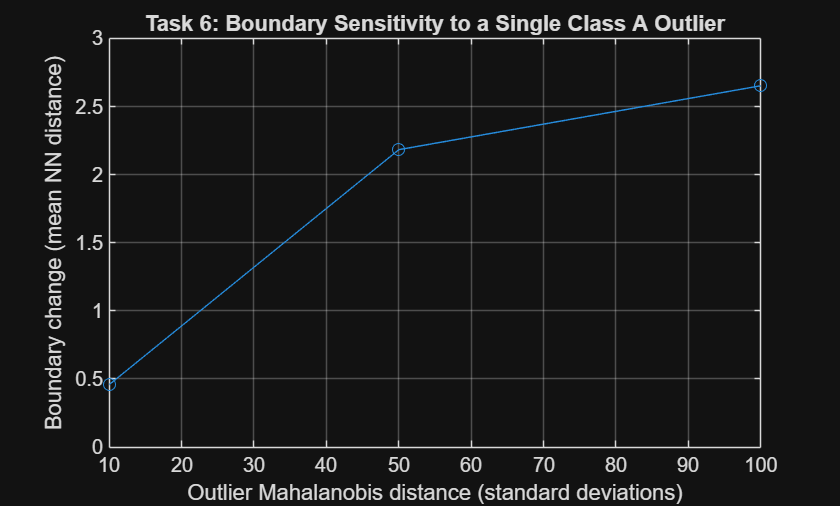


figure;
plot(outlierDistances, outlierChange, '-o');
xlabel('Outlier Mahalanobis distance (standard deviations)');
ylabel('Boundary change (mean NN distance)');
title('Task 6: Boundary Sensitivity to a Single Class A Outlier');
grid on;

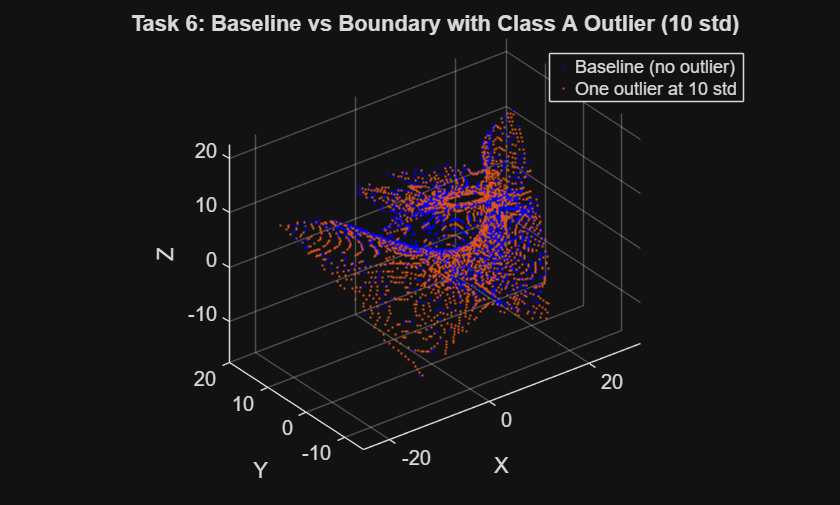

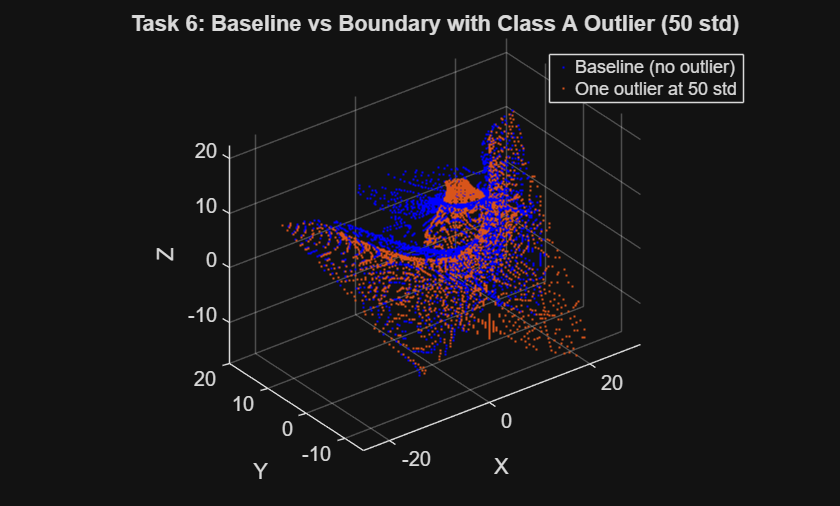

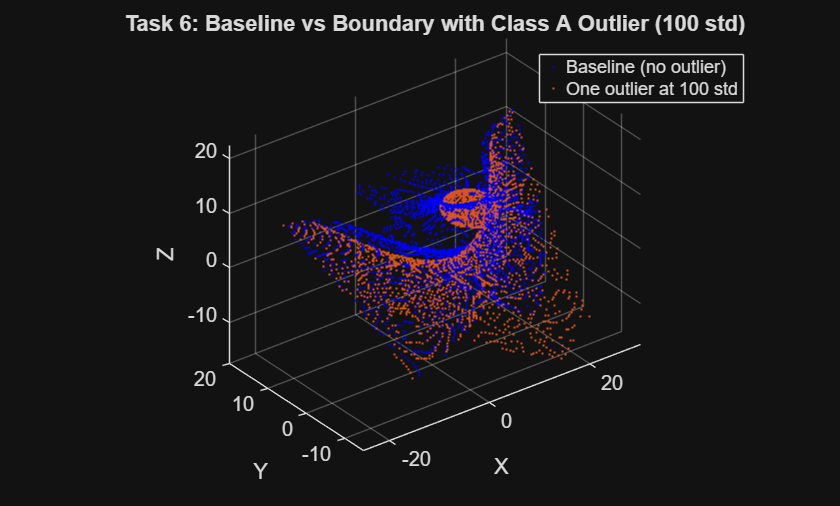

 
%% Overlays: baseline vs boundary with the outlier
for i = 1:length(outlierDistances)
    b = outlierBoundaries{i};
 
    figure;
    hold on;
    plot3(baselineEstBoundary(:,1), baselineEstBoundary(:,2), baselineEstBoundary(:,3), '.', 'Color', 'b', 'MarkerSize', 3, 'DisplayName', 'Baseline (no outlier)');
    plot3(b(:,1), b(:,2), b(:,3), '.', 'Color', [0.85 0.33 0.1], 'MarkerSize', 3, 'DisplayName', sprintf('One outlier at %d std', outlierDistances(i)));
    xlabel('X'); ylabel('Y'); zlabel('Z');
    title(sprintf('Task 6: Baseline vs Boundary with Class A Outlier (%d std)', outlierDistances(i)));
    legend show; grid on; axis equal; view(3);
end

One single outlier can greatly affect the Bayes decision boundaries since the class parameters are learned from data. An additional data point to Class A (0.1% of data samples -> 1000 points to 1001 samples) at distances of 10, 50 and 100 standard deviations from its mean caused the boundaries to shift by mean nearest-neighbour distances of 0.459, 2.18 and 2.65. This is already comparable to the 0.5 unit mean shift observed in Task 2 at 10 standard deviations.

The effect is almost entirely due to the variance. The class mean has changed only by 0.022 to 0.216 units, while an outlier located at distance d increases the sample variance in its direction by approximately d²/K, meaning that the determinant of the variance has increased by roughly 1.1, 3.5 and 11 times correspondingly. The reason for that is that the discriminant depends on inv(sigma) and log(det(sigma)), which means that Class A's distribution becomes wider and lower, hence affecting the decision boundaries near this class.

Task 7:

For real-world data analysis problems,

        (a) Could the nature of the class decision boundaries effective be driven by only a few data points within the data?

        (b) Is it correct (or appropriate) to have decision boundaries that exhibit high sensitivities to only a small number of data samples?

        (c) How would you detect this?

        (d) How would you resolve this?

%{
(a) Yes. Since the Bayes decision boundary is based on the class means and covariance, and both are 
estimated using samples and hence, affected by each individual point. For example, in Task 6, 
an addition of one point (which was 0.1% of Class A) changed the Bayes decision boundary up to 2.65 units 
while the change in class mean was just 0.2 units. If a point is far away from the class center, it has 
large leverage because its influence on the estimation of the covariance matrix is proportional to the 
square of its distance from the center, but influence on estimation is proportional to 1/K.

(b) In general, it is not because A boundary has to depend on the structure of the class and not any 
particular oddball observation. In this case, the boundary depends on one point so much that if another 
training sample were used, then the resulting boundary would be significantly different, meaning that the 
classifier has high variance and is expected to perform poorly. Also, the observation might be an error 
in measurements or mislabeling of the sample. However, in the case when the point happens to be a rare but 
true event, for example, the fault case, it should be taken into consideration deliberately.

(c)
- Leave-One-Out Influence: Fit the parameters and boundary omitting one observation at a time and calculate 
how much the fit changes using the boundary change criterion employed before. Those observations that cause 
the boundary to change drastically when omitted have influence.

- Bootstrap Resampling: Reestimate the boundary using many bootstrap samples. Large variation in the boundary 
indicates sensitivity to the sample chosen.

- Mahalanobis Screening: Flag observations with large Mahalanobis distance to class mean. This should be done 
using robust statistics since an outlier will increase the classical covariance and hence mask itself.

- Classical vs Robust Comparison: If the usual mean and covariance values differ dramatically from robust 
estimates, there must be some outliers.

(d) 
- Robust estimation: Adopt robust estimators like minimum covariance determinants or trimmed estimates, where 
no few observations can influence.

- Data examination: Investigate any observations that trigger alerts for their errors or misclassification, 
and delete them only with an explanation.

- Regularization: Regularize the covariance estimator by shrinking or pooling covariances among the classes, 
thus minimizing dependence on observations from a particular class.

- Heavy-tailed distribution: Switch to heavy-tailed distribution for the density of classes instead of Gaussian 
density, thus giving less weight to extreme points.

- Increase data: Increase the number of observations, particularly those belonging to smaller classes, because 
the influence of any observation decreases as 1/K.

- Boundary validation: Conduct validation of the boundary after any solution through bootstrap or cross-validation
 procedure.
%}